% Close all open figure windows
close all;
% Remove all variables from the workspace
clear;
% Clear the command window
clc;

% close all open figures
close all
%clear the work space
clear
%clear the command window
clc

unzip('CoffeXpert.zip', 'CoffeDataset');

if exist('CoffeDataset/test/red_spider_mite', 'dir')
    movefile('CoffeDataset/test/red_spider_mite/*', ...
             'CoffeDataset/test/red spider mite/');
    rmdir('CoffeDataset/test/red_spider_mite');
    fprintf('Test folder renamed.\n');
end

imds = imageDatastore('/MATLAB Drive/dataset/Train', ...
    'IncludeSubfolders', true, ...
    'LabelSource',       'foldernames');

The first challenge was locating the dataset correctly. Initially we used a relative path (`CoffeDataset/train`) which told MATLAB to look for the folder in its current working directory. This failed because the dataset was stored in a different location on MATLAB Drive. The solution was to use an absolute path (`/MATLAB Drive/dataset/Train`) which gives MATLAB the exact location of the images from the root of the drive, eliminating any ambiguity.

disp(countEachLabel(imds))

         Label         Count
    _______________    _____

    Rust                282 
    healthy             282 
    red spider mite     136 



a smart catalogue of all the images, each one already labelled, ready for the next steps.

figure('Name', 'Sample Images per Class');
classNames = categories(imds.Labels);
numClasses = numel(classNames);

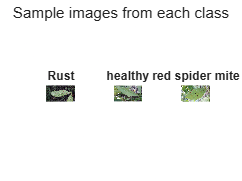

for c = 1:numClasses
    idx = find(imds.Labels == classNames{c}, 1);
    img = readimage(imds, idx);
    subplot(1, numClasses, c);
    imshow(img);
    title(classNames{c}, 'Interpreter', 'none');
end
sgtitle('Sample images from each class');

find the position of the first `healthy` image , open it , show it

find the position of the first `Rust` image , open it , show it

find the position of the first `red spider mite` image ,open it , show it

INPUT_SIZE = [128 128 3];

warning('off', 'MATLAB:imagesci:jpeg:libraryMessage');

imds.ReadFcn = @(filename) safeReadAndResize(filename, INPUT_SIZE(1:2));

preprocessing, changing evrytime an image passess through here the size is changed to 128 * 128 * 3

All images in the dataset come in varying dimensions. A CNN requires every input image to be exactly the same size. We set a fixed input size of 128×128×3 pixels and applied this using MATLAB's `imresize` function through the datastore's `ReadFcn` property. This means every time MATLAB reads an image it automatically resizes it — no manual processing needed.

%% AUGMENTATION
augmenter = imageDataAugmenter( ...
    'RandXReflection',  true, ...
    'RandYReflection',  true, ...
    'RandRotation',     [-30 30], ...
    'RandXTranslation', [-10 10], ...
    'RandYTranslation', [-10 10]);

Because the dataset only contains 700 images total, which is relatively small for training a deep learning model, we applied data augmentation to artificially increase the variety of training data. This included random horizontal and vertical flipping, random rotation between -30 and +30 degrees, and random translation in both x and y directions. This helps the model generalise better to real world images where coffee leaves may appear at different angles, orientations and positions.

[trainDS, valDS, testDS] = splitEachLabel(imds, 0.70, 0.15, 0.15, 'randomized');

fprintf('Train:      %d images\n', numel(trainDS.Files));

Train:      489 images


fprintf('Validation: %d images\n', numel(valDS.Files));

Validation: 107 images


fprintf('Test:       %d images\n', numel(testDS.Files));

Test:       104 images


A further challenge was encountered when running the split step. Because the code was being run line by line in the Command Window rather than as a complete script, the `imds` variable was lost from memory when `clc; clear;` was executed at the start of a new session. MATLAB's `clear` command wipes all variables from the workspace, meaning `imds` no longer existed when `splitEachLabel` tried to use it. The solution was to combine all code into a single script and run it from top to bottom in one go, ensuring every variable was created in the correct order before being used.

INPUT_SIZE = [128 128 3];
inputLayer = imageInputLayer(INPUT_SIZE, 'Name', 'input', 'Normalization', 'zerocenter');
disp(inputLayer)

  ImageInputLayer with properties:

                      Name: 'input'
                 InputSize: [128 128 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: []



%this creates the first layer of our CNN. The input layer. It's the entrance door of the network. We're telling it to expect images of exactly 128×128×3.

conv1 = convolution2dLayer(3, 32, 'Padding', 'same', 'Name', 'conv1');
disp(conv1)

  Convolution2DLayer with properties:

              Name: 'conv1'

   Hyperparameters
        FilterSize: [3 3]
       NumChannels: 'auto'
        NumFilters: 32
            Stride: [1 1]
    DilationFactor: [1 1]
       PaddingMode: 'same'
       PaddingSize: []
      PaddingValue: 0

   Learnable Parameters
           Weights: []
              Bias: []

  Show all properties



% Layer 1: Convolution - scans image with 32 filters of size 3x3

% Layer 2: Batch Normalisation - keeps numbers stable during training Is basically saying
% :Create a batch normalisation layer and give it name as bn1
bn1 = batchNormalizationLayer('Name', 'bn1');

% Layer 3: ReLU - removes negative values, adds non-linearity
relu1 = reluLayer('Name', 'relu1');

% Layer 4: MaxPooling - shrinks image from 128x128 to 64x64
pool1 = maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool1');

disp('Block 1 created successfully')

Block 1 created successfully


%BLOCK 2 (learns shapes and textures)

% Layer 5: Convolution - now uses 64 filters to find more complex features
conv2 = convolution2dLayer(3, 64, 'Padding', 'same', 'Name', 'conv2');

% Layer 6: Batch Normalisation
bn2 = batchNormalizationLayer('Name', 'bn2');

% Layer 7: ReLU
relu2 = reluLayer('Name', 'relu2');

% Layer 8: MaxPooling - shrinks image from 64x64 to 32x32
pool2 = maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool2');

disp('Block 2 created successfully')

Block 2 created successfully


%% BLOCK 3 (learns high-level features)
conv3 = convolution2dLayer(3, 128, 'Padding', 'same', 'Name', 'conv3');
bn3   = batchNormalizationLayer('Name', 'bn3');
relu3 = reluLayer('Name', 'relu3');
pool3 = maxPooling2dLayer(2, 'Stride', 2, 'Name', 'pool3');

disp('Block 3 created successfully')

Block 3 created successfully


%16×16×128 grid is what gets handed to the fully connected layers next
%since we are adding filters block by block from 3 to 2 to 64 to 128 while 
%maxpool reduces the pixel size by half evry block from 128*128 to 64*64 to
%32*32 to 16*16

%% FULLY CONNECTED HEAD
flatLayer = flattenLayer('Name', 'flatten');

fc1   = fullyConnectedLayer(256, 'Name', 'fc1');
relu4 = reluLayer('Name', 'relu4');
drop1 = dropoutLayer(0.5, 'Name', 'drop1');

fc2      = fullyConnectedLayer(3, 'Name', 'fc2');
softmaxOut = softmaxLayer('Name', 'softmax');
classOut   = classificationLayer('Name', 'output');

disp('Fully connected head created successfully')

Fully connected head created successfully


layers = [
    inputLayer
    conv1; bn1; relu1; pool1      % Block 1
    conv2; bn2; relu2; pool2      % Block 2
    conv3; bn3; relu3; pool3      % Block 3
    flatLayer
    fc1; relu4; drop1
    fc2
    softmaxOut
    classOut
];

lgraph = layerGraph(layers);
disp('Network assembled successfully');

Network assembled successfully


options = trainingOptions('adam', ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 32, ...
    'ValidationData', augmentedImageDatastore(INPUT_SIZE, valDS), ...
    'ValidationFrequency', 10, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', true, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.5, ...
    'LearnRateDropPeriod', 10);

Introduce ADAM as the learning algorithm, training is expected to make 2 full pass,32 images are feed into the system at a time with the images shuffled in every epoch, after ever 10 epoch cut the learning rate by 1/2

augTrainDS = augmentedImageDatastore(INPUT_SIZE, trainDS, ...
    'DataAugmentation', augmenter);

augValDS = augmentedImageDatastore(INPUT_SIZE, valDS);
augTestDS = augmentedImageDatastore(INPUT_SIZE, testDS);

disp('Augmented datastores created');

Augmented datastores created


Augment Train, Validate and Test dataset using the augmenter(resizing only test and validate data, the training data is also resized plus rotated and flipped

function img = safeReadAndResize(filename, targetSize)
    try
        img = imresize(imread(filename), targetSize);
        if size(img, 3) == 1
            img = repmat(img, [1 1 3]);
        end
    catch
        img = zeros([targetSize 3], 'uint8');
    end
end

[trainedNet, trainInfo] = trainNetwork(augTrainDS, lgraph, options);

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:16 |       46.88% |       40.19% |       1.7894 |      45.8009 |          0.0010 |


|       1 |          10 |       00:00:35 |       31.25% |       40.19% |      14.3478 |      11.7077 |          0.0010 |


|       2 |          20 |       00:00:54 |       28.12% |       41.12% |      11.6330 |       8.8734 |          0.0010 |


|       2 |          30 |       00:01:14 |       40.62% |       42.06% |       3.2875 |       2.5146 |          0.0010 |


|       3 |          40 |       00:01:33 |       40.62% |       47.66% |       1.4463 |       1.0593 |          0.0010 |


|       4 |          50 |       00:01:53 |       62.50% |       42.99% |       1.0375 |       1.0402 |          0.0010 |


|       4 |          60 |       00:02:12 |       31.25% |       41.12% |       1.0641 |       1.0454 |          0.0010 |


|       5 |          70 |       00:02:32 |       37.50% |       40.19% |       1.1795 |       1.0307 |          0.0010 |


|       6 |          80 |       00:02:51 |       40.62% |       42.06% |       1.0657 |       1.0361 |          0.0010 |


|       6 |          90 |       00:03:11 |       34.38% |       39.25% |       1.0388 |       1.0114 |          0.0010 |


|       7 |         100 |       00:03:30 |       43.75% |       42.99% |       1.0095 |       1.0185 |          0.0010 |


|       8 |         110 |       00:03:50 |       50.00% |       44.86% |       0.9593 |       1.0001 |          0.0010 |


|       8 |         120 |       00:04:10 |       40.62% |       45.79% |       1.0676 |       0.9789 |          0.0010 |


disp('Training complete');

YPred = classify(trainedNet, augTestDS);
YTrue = testDS.Labels;

accuracy = sum(YPred == YTrue) / numel(YTrue) * 100;
fprintf('Test Set Accuracy: %.2f%%\n', accuracy);

figure('Name', 'Confusion Matrix');
confusionchart(YTrue, YPred, ...
    'Title', 'Test Set Confusion Matrix', ...
    'RowSummary', 'row-normalized', ...
    'ColumnSummary', 'column-normalized');

figure('Name', 'Training Accuracy Curve');
epochs = 1:length(trainInfo.TrainingAccuracy);

plot(epochs, trainInfo.TrainingAccuracy, 'b-', 'LineWidth', 2);
hold on;
plot(epochs, trainInfo.ValidationAccuracy, 'r--', 'LineWidth', 2);
xlabel('Epoch');
ylabel('Accuracy (%)');
title('Training and Validation Accuracy Over Epochs');
legend('Training Accuracy', 'Validation Accuracy');
grid on;

save('coffeXpert_model.mat', 'trainedNet');
disp('Model saved successfully');